global nos elementos dTdn Tinf hbarra Lbarra ki dTdntipo nosCC TCC
format shortG

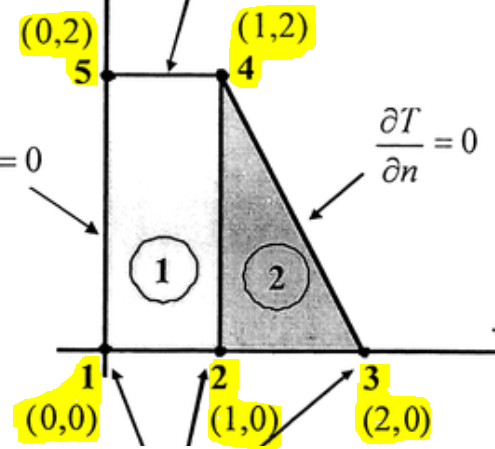

%nos=[0 0; 1 0; 2 0; 1 2; 0 2]; 2013, imagem acima
%nos=[0 0; 2 0; 2 1; 0 1]; 2016
%nos=[0 0; 0.1 0; 0.1 0.2; 0 0.2; 0.3 0.2]; 2011
%nos=[0 0; 0.1 0; 0.1 0.2; 0 0.2; 0.3 0.2]; 2018
%nos=[0 0; 2 0; 2 1; 0 1;4 0]; 2019

**Coloque os nós do exercicio como no exemplo acima**

%Inserir aqui as coordenadas dos nos no espaço
nos=[0 0; 1 0; 2 0; 1 2; 0 2];

**Coloque aqui os nós de temperaturas conhecidas e o valor das temperaturas conhecidas**

%Nós que conheco a temperatura
%Temperatura conhecida
%nosCC=[1 1 1 0 0]; %2013
%TCC=[50 50 50 0 0]; %2013
%nosCC=[1 1 0 0]; 2016
%TCC=[10 10 0 0]; 2016
nosCC=[1 1 1 0 0]; %2013
TCC=[50 50 50 0 0]; %2013

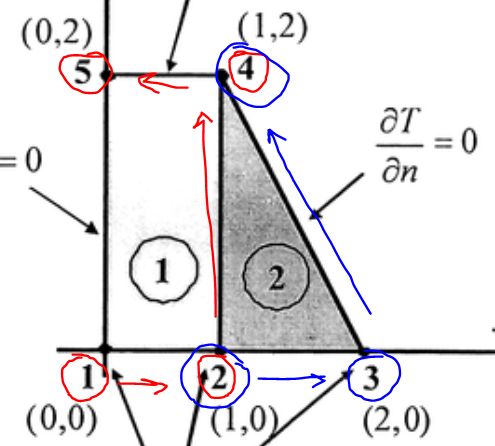

%elementos=[1 2 4 5;2 3 4 0]; 2013, imagem acima
%elementos=[1 2 3 4]; 2016
%elementos=[1 2 3 4; 2 5 3 0]; 2011
%elementos=[1 2 3 4; 2 5 3 0]; 2018
%elementos=[1 2 3 4; 2 5 0 0]; 2019

**Coloque os nós de cada figura como no exemplo acima**

%Inserir aqui, na ordem antihoraria, os nos dos elementos
%Caso seja triangulo e nao quadrilatero, por um 0 no fim
%Caso seja uma barra, por 2 zeros no fim
%Se for quadrado, começa do extremo inferior esquerdo
elementos=[1 2 4 5;2 3 4 0];

**Coloquei aqui os k **

%Inserir aqui os k de cada elemento
%ki=[1 2]; 2013
%ki=[2]; 2016
%ki=[2 1]; 2011
%ki=[2 1]; 2018
%ki=[2 1]; 2019
ki=[1 2];
Carregamento=1;

**Coloque aqui os dados da barra**

%Convecção em barra - caso tenha - se não for barra só põe 0 e foda se
hbarra=[0 0];
Lbarra=2;

**Coloque aqui as condições de contorno**

%Insere indices das condições de contorno por contorno
%Se for triangular ou barra, nas posicoes extras poe dTdntipo=-1
%dT/dn=cte -> dTdntipo=1
%kdT/dn=-h(T-Tinf) -> dTdntipo=2
%dT/dn=-a*T -> dTdntipo=2 também
%dT/dn=desconhecido -> dTdntipo=3
%dT/dn=interface -> dTdntipo=4
%Primeiro elemento é contorno do nó 1 pro 2 e assim por diante
%dTdntipo=[3 4 2 1; 3 1 4 -1]; 2013, imagem acima
%dTdntipo=[3 1 1 2]; 2016
%dTdntipo=[2 4 3 1; 1 3 4 -1]; 2011
%dTdntipo=[1 4 3 1; 1 3 4 -1]; 2018
%dTdntipo=[1 1 3 1; 2 -1 -1 -1]; 2019
dTdntipo=[3 4 2 1; 3 1 4 -1];
%Aqui coloca o valor de dTdn, caso seja constante.
%Coloca o valor de -a, caso seja do tipo 3. Coloca o valor de -k*h caso seja
%tipo 2
%Caso seja tipo -1, 3 ou 4, poe 1000
%dTdn=[1000 1000 2 0; 1000 0 1000 1000]; 2013, imagemm acima
%dTdn=[1000 2 0 1]; 2016
%dTdn=[20 1000 1000 0; 0 1000 1000 1000]; 2011
%dTdn=[2 1000 1000 0; 0 1000 1000 1000]; 2018
%dTdn=[2 0 1000 0; 2 1000 1000 1000]; 2019
dTdn=[1000 1000 2 0; 1000 0 1000 1000];
%Se não tiver, poe Inf pra saber onde da matriz por a convecção
%Tinf=Inf; 2013, imagem acima
%Tinf=Inf; 2016
%Tinf=30; 2011
%Tinf=Inf; 2018
%Tinf=30; 2019
Tinf=Inf;

Para calcular [Ke] lembre-se das fórmulas:

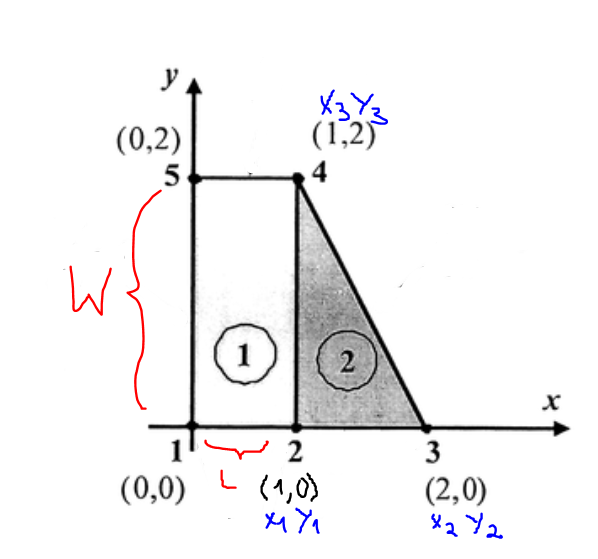

**Triângulo**

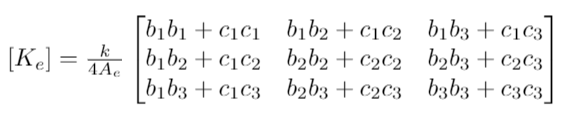

i1 = nó local 1 ,  i2 = nó local 2   , i3 = nó local 3

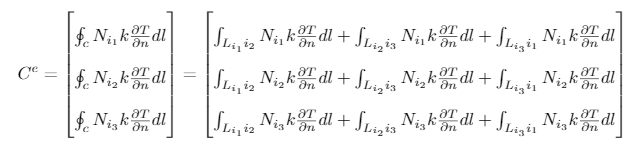

**Quadrilátero**

**W = altura**

**L = Lbarra = largura**

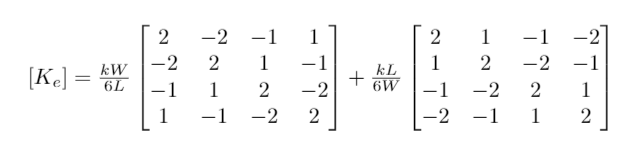

i1 = nó local 1 ,  i2 = nó local 2   , i3 = nó local 3  ,  i4 = nó local 4

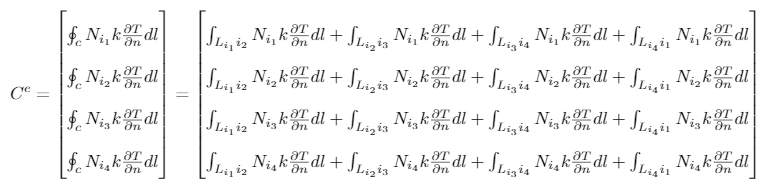

**Barra**

**L = comprimento**

**h = coeficiente convectivo**

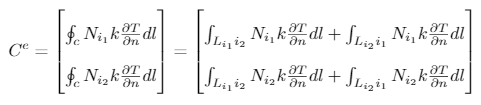

Kglobal=zeros(length(nos(:,1)));
Kglobal2=zeros(length(nos(:,1)));
Fglobal=zeros(length(nos(:,1)),length(find(elementos~=0)));
bc=zeros(3,2);
nosconveccao=[];
Kglobsadd=[];
for i=1:length(elementos(:,1))
    elemento=find(elementos(i,:)==0);
    if (isempty(elemento)) %quadrilatero
        display('Quadrilátero')
        L=nos(elementos(i,2),1)-nos(elementos(i,1),1)
        W=nos(elementos(i,4),2)-nos(elementos(i,1),2)
        K = ki(i)
        Kele1=ki(i)*L/(6*W)*[2 1 -1 -2;1 2 -2 -1; -1 -2 2 1; -2 -1 1 2];
        Kele2=ki(i)*W/(6*L)*[2 -2 -1 1; -2 2 1 -1; -1 1 2 -2; 1 -1 -2 2];
        Kele=Kele1+Kele2
        [Fele,nosconveccao,Kglobsadd]=F(Kele,i,Kglobal,nosconveccao,Kglobsadd)
        Fele
        display('NaN -> dT/dn=desconhecido')        
        display('9999 -> dT/dn=interface')
        display('Inf -> dT/dn=a*T ou  dT/dn=h(T-Tinf)')
    elseif length(elemento)==1 %triangulo
        display('Triângulo')
        bc(1,1)=nos(elementos(i,2),2)-nos(elementos(i,3),2);
        bc(2,1)=nos(elementos(i,3),2)-nos(elementos(i,1),2);
        bc(3,1)=nos(elementos(i,1),2)-nos(elementos(i,2),2);
        bc(1,2)=nos(elementos(i,3),1)-nos(elementos(i,2),1);
        bc(2,2)=nos(elementos(i,1),1)-nos(elementos(i,3),1);
        bc(3,2)=nos(elementos(i,2),1)-nos(elementos(i,1),1);
        Ae=0.5*(bc(1,1)*bc(2,2)-bc(2,1)*bc(1,2))
        K = ki(i)
        Kele=zeros(3,3);
        Kele(1,:)=[dot(bc(1,:),bc(1,:)) dot(bc(1,:),bc(2,:)) dot(bc(1,:),bc(3,:))];
        Kele(2:3,1)=Kele(1,2:3)';
        Kele(2,2:3)=[dot(bc(2,:),bc(2,:)) dot(bc(2,:),bc(3,:))];
        Kele(3,2)=Kele(2,3);
        Kele(3,3)=dot(bc(3,:),bc(3,:));
        Kele=ki(i)/(4*Ae)*Kele  
        [Fele,nosconveccao,Kglobsadd]=F(Kele,i,Kglobal,nosconveccao,Kglobsadd);
        Fele
        display('NaN -> dT/dn=desconhecido')        
        display('9999 -> dT/dn=interface')
        display('Inf -> dT/dn=a*T ou  dT/dn=h(T-Tinf)')
     else %barra pq o emilio eh um lixo fudido
        display('Barra')
        h_barra = hbarra(i)
        Lbarra
        K = ki(i)
        Kele1=ki(i)/Lbarra*[1 -1; -1 1];
        Kele2=hbarra(i)*(Lbarra/3)*[1 0.5; 0.5 1];
        Kele=Kele1-Kele2
        [Fele,nosconveccao,Kglobsadd]=F(Kele,i,Kglobal,nosconveccao,Kglobsadd);        
        Fele
        display('NaN -> dT/dn=desconhecido')        
        display('9999 -> dT/dn=interface')
        display('Inf -> dT/dn=a*T ou  dT/dn=h(T-Tinf)')
    end
    display(' ')
    Kglobal=incrementaKglobal(Kglobal,Kele,i);
    Fglobal=incrementaFglobal(Fglobal,Fele,i);
end

Quadrilátero


L =      1


W =      2


K =      1


Kele =       0.83333     -0.58333     -0.41667      0.16667
     -0.58333      0.83333      0.16667     -0.41667
     -0.41667      0.16667      0.83333     -0.58333
      0.16667     -0.41667     -0.58333      0.83333


Fele =          NaN           0           0           0
         NaN        9999           0           0
           0        9999         Inf           0
           0           0         Inf           0


nosconveccao =      4     5


Kglobsadd =       0.66667      0.33333
      0.33333      0.66667


Fele =          NaN           0           0           0
         NaN        9999           0           0
           0        9999         Inf           0
           0           0         Inf           0


NaN -> dT/dn=desconhecido


9999 -> dT/dn=interface


Inf -> dT/dn=a*T ou  dT/dn=h(T-Tinf)


Triângulo


Ae =      1


K =      2


Kele =           2.5           -2         -0.5
           -2            2            0
         -0.5            0          0.5


Fele =          NaN           0        9999
         NaN           0           0
           0           0        9999


NaN -> dT/dn=desconhecido


9999 -> dT/dn=interface


Inf -> dT/dn=a*T ou  dT/dn=h(T-Tinf)


Kglobal

Kglobal =       0.83333     -0.58333            0     -0.41667      0.16667
     -0.58333       3.3333           -2     -0.33333     -0.41667
            0           -2            2            0            0
     -0.41667     -0.33333            0       1.3333     -0.58333
      0.16667     -0.41667            0     -0.58333      0.83333


%Nan -> dT/dn=desconhecido
%9999 -> dT/dn=interface
%Inf -> dT/dn=a*T ou  dT/dn=h(T-Tinf)
Fglobal

Fglobal =          NaN           0           0           0           0           0           0
         NaN        9999           0           0         NaN           0        9999
           0           0           0           0         NaN           0           0
           0        9999         Inf           0           0           0        9999
           0           0         Inf           0           0           0           0


Coeficientes_add = Kglobsadd*-1

Coeficientes_add =      -0.66667     -0.33333
     -0.33333     -0.66667


%Coeficientes_add, se houver, são os coeficientes do sistema em relação as temperaturas onde tem convecção')
%Somar na matriz Fele, colocando na linha/coluna correspondentes das temperaturas')


Kpreglobs=Kglobal;
Fglobs=AjeitaFglobal(Fglobal)

Fglobs =      0
     0
     0
     0
     0


Kglobal2=mudaKglobal(Kglobal,nosconveccao,Kglobsadd)

Kglobal2 =       0.83333     -0.58333            0     -0.41667      0.16667
     -0.58333       3.3333           -2     -0.33333     -0.41667
            0           -2            2            0            0
     -0.41667     -0.33333            0            2        -0.25
      0.16667     -0.41667            0        -0.25          1.5


[Fglobs,Fglobs2,Kglobal,Kglobal2]=Montasistema(Kglobal,Kglobal2,Fglobs);
%vetor final de carregamentos
Fglobs

Fglobs =            50
           50
           50
         37.5
         12.5


%Incognitas encontradas:
Resolvesistema(Fglobs2,Kglobal2)

A =        20.213
       11.702


function Resolvesistema(Fglobs2,Kglobal2)
    global nosCC
    Kmini=zeros(2,2);
    Fmini=zeros(2,1);
    manter=find(nosCC==0);
    Kmini(1,1)=Kglobal2(manter(1),manter(1));
    Kmini(1,2)=Kglobal2(manter(1),manter(2));
    Kmini(2,1)=Kglobal2(manter(2),manter(1));
    Kmini(2,2)=Kglobal2(manter(2),manter(2));
    Fmini(1)=Fglobs2(manter(1));
    Fmini(2)=Fglobs2(manter(2));
    A=Kmini\Fmini
end

function [Fglobs,Fglobs2,Kglobal,Kglobal2]=Montasistema(Kglobal,Kglobal2,Fglobs)
    global nosCC TCC
    for i=1:length(Kglobal)
        if nosCC(i)==1
            Fglobs=Fglobs-Kglobal(:,i)*TCC(i);
            Kglobal(i,:)=0;
            Kglobal(:,i)=0;
            Kglobal(i,i)=1;
            Fglobs2=Fglobs-Kglobal2(:,i)*TCC(i);
            Kglobal2(i,:)=0;
            Kglobal2(:,i)=0;
            Kglobal2(i,i)=1;            
        end
    end
    Fglobs(find(nosCC==1))=TCC(find(nosCC==1));
    Fglobs2(find(nosCC==1))=TCC(find(nosCC==1));
end

function Kglobal2=mudaKglobal(Kglobal,nosconveccao,Kglobsadd)
    Kglobal2=Kglobal;
    Kglobal2(nosconveccao(1),nosconveccao(1))=...
    Kglobal2(nosconveccao(1),nosconveccao(1))+Kglobsadd(1,1);
    Kglobal2(nosconveccao(1),nosconveccao(2))=...
    Kglobal2(nosconveccao(1),nosconveccao(2))+Kglobsadd(1,2);
    Kglobal2(nosconveccao(2),nosconveccao(1))=...
    Kglobal2(nosconveccao(2),nosconveccao(1))+Kglobsadd(2,1);
    Kglobal2(nosconveccao(2),nosconveccao(2))=...
    Kglobal2(nosconveccao(2),nosconveccao(2))+Kglobsadd(2,2);

end

function Fglobs=AjeitaFglobal(Fglobal)
    Fglobs=zeros(length(Fglobal(:,1)),1);
    for i=1:length(Fglobal(:,1))
        for j=1:length(Fglobal(1,:))
            if Fglobal(i,j)~=9999 && Fglobal(i,j)~=Inf && (~isnan(Fglobal(i,j)))
                Fglobs(i)=Fglobs(i)+Fglobal(i,j);
            end
        end
    end
end

function Fglobal=incrementaFglobal(Fglobal,Fele,i)
    global elementos
    for j=1:length(elementos)
        forma=length(find(elementos(i,:)==0));
        forma1=length(find(elementos(1,:)~=0));
        for k=1:length(elementos)-forma
            if elementos(i,j)~=0 && elementos(i,k)~=0
                m=elementos(i,j);
                n=k;
                if i==1
                    Fglobal(m,n)=Fglobal(m,n)+Fele(j,k);
                else
                    Fglobal(m,n+forma1)=Fglobal(m,n+forma1)+Fele(j,k);
                end
            end
        end
    end
end

function Kglobal=incrementaKglobal(Kglobal,Kele,i)
    global elementos
    for j=1:length(elementos)
        for k=1:length(elementos)
            if elementos(i,j)~=0 && elementos(i,k)~=0
                m=elementos(i,j);
                n=elementos(i,k);
                Kglobal(m,n)=Kglobal(m,n)+Kele(j,k);
            end
        end
    end
end

%Deixar -1000 na matriz F de onde tem que cortar
%Substituir quando for por na global
function [Fele,nosconveccao,Kglobsadd]=F(Kele,i,Kglobal,nosconveccao,Kglobsadd)
    global dTdn Tinf hbarra Lbarra elementos nos ki dTdntipo
    Fele=ones(length(Kele));
    for j=1:length(Kele) %Ns
        for k=1:length(Kele) %Contornos
            zerei=0;
            forma=find(elementos(i,:)==0);
            if k+1<=length(elementos(i,:))-length(forma)
                if elementos(i,j)~=elementos(i,k) && elementos(i,j)~=elementos(i,k+1)
                    %Tem que zerar porque é Nj no contorno Lik
                    Fele(j,k)=0;
                    zerei=1;
                end
            elseif elementos(i,j)~=elementos(i,k) && elementos(i,j)~=elementos(i,1)
                %Tem que zerar porque é Nj no contorno Lik
                Fele(j,k)=0;
                zerei=1;
            end
            if zerei==0
                if dTdntipo(i,k)==1 
                    %dT/dn=cte -> dTdntipo=1
                    cte=dTdn(i,k);
                    if k+1<=length(elementos(i,:))-length(forma)
                        if nos(elementos(i,k),1)==nos(elementos(i,k+1),1)
                            dij=abs(nos(elementos(i,k),2)-nos(elementos(i,k+1),2));
                        else
                            dij=abs(nos(elementos(i,k),1)-nos(elementos(i,k+1),1));
                        end
                    else
                        if nos(elementos(i,k),1)==nos(elementos(i,1),1)
                            dij=abs(nos(elementos(i,k),2)-nos(elementos(i,1),2));
                        else
                            dij=abs(nos(elementos(i,k),1)-nos(elementos(i,1),1));
                        end                       
                    end
                    calc=ki(i)*cte*(dij)/2; 
                    Fele(j,k)=calc;
                elseif dTdntipo(i,k)==2
                    %dT/dn=-h(T-Tinf) -> dTdntipo=2
                    %dT/dn=-a*T -> dTdntipo=2
                    if k+1<=length(elementos(i,:))-length(forma)
                        if length(nosconveccao)==0
                            nosconveccao=[elementos(i,k) elementos(i,k+1)];
                        end
                        if nos(elementos(i,k),1)==nos(elementos(i,k+1),1)
                            Fele(j,k)=Tinf*dTdn(i,k)*0.5*abs(nos(elementos(i,k),2)-nos(elementos(i,k+1),2));
                            if length(Kglobsadd)==0
                                Kglobsadd=dTdn(i,k)*abs(nos(elementos(i,k),2)-nos(elementos(i,k+1),2))*[1/3 1/6; 1/6 1/3];
                            end
                        else
                            Fele(j,k)=Tinf*dTdn(i,k)*0.5*abs(nos(elementos(i,k),1)-nos(elementos(i,k+1),1));  
                            if length(Kglobsadd)==0
                                Kglobsadd=dTdn(i,k)*abs(nos(elementos(i,k),1)-nos(elementos(i,k+1),1))*[1/3 1/6; 1/6 1/3];
                            end                        
                        end
                    else
                        if length(nosconveccao)==0
                            nosconveccao=[elementos(i,k) elementos(i,1)];
                        end
                        if nos(elementos(i,k),1)==nos(elementos(i,1),1)
                            Fele(j,k)=Tinf*dTdn(i,k)*0.5*abs(nos(elementos(i,k),2)-nos(elementos(i,1),2));
                            if length(Kglobsadd)==0
                                Kglobsadd=dTdn(i,k)*abs(nos(elementos(i,k),2)-nos(elementos(i,1),2))*[1/3 1/6; 1/6 1/3];
                            end                        
                        else
                            Fele(j,k)=Tinf*dTdn(i,k)*0.5*abs(nos(elementos(i,k),1)-nos(elementos(i,1),1));
                            if length(Kglobsadd)==0
                                Kglobsadd=dTdn(i,k)*abs(nos(elementos(i,k),1)-nos(elementos(i,1),1))*[1/3 1/6; 1/6 1/3];
                            end                        
                        end   
                    end
                elseif dTdntipo(i,k)==3
                    %dT/dn=desconhecido -> dTdntipo=3
                    Fele(j,k)=NaN;
                elseif dTdntipo(i,k)==4
                    %dT/dn=interface -> dTdntipo=4 
                    Fele(j,k)=9999;
                end
            end
        end
    end

end